# Math420 - Group Project

Authors: Robert 'Eddie' Bull, Thokozani Tembo

epsilon = 4.0960

10 largest Eigenvalues: 312612791.8012
24395418.69816
0.4933503749385
0.4558580609087
0.3930258070909
0.368043830551
0.3479964227247
0.3259990213198
0.317197638384
0.2917258746291


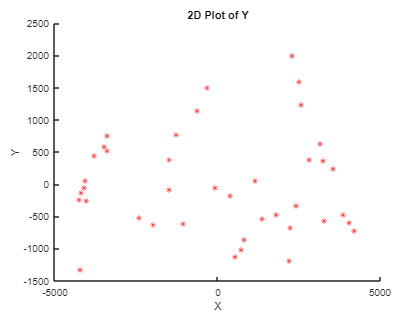

N = 2

t_coords = 1.0e+03 *

   -5.5726    2.8398
   -6.7292    2.9628
   -8.3267    3.2198
   -4.9611    2.9207
   -6.2027    3.0146
   -5.5449    2.4943
   -6.7126    3.4465
   -5.4005    2.7078
   -5.3839    2.3658
   -5.2202    2.7466


Q_det = -1.0000

t_coords = 1.0e+03 *

   -6.1937    3.1065
   -6.0687    2.9269
   -6.7099    3.1024
   -5.2457    3.0388
   -6.3803    2.9366
   -5.0474    2.8709
   -5.3224    2.6871
   -5.4682    2.8916
   -8.1761    3.1832
   -6.7119    2.1799


Q_det = -1.0000

t_coords = 1.0e+03 *

   -7.1625    2.8930
   -5.1096    2.9587
   -5.6029    2.2166
   -5.8282    3.2123
   -5.7024    1.8891
   -8.4794    2.6560
   -7.3207    2.4653
   -8.2707    2.3782
   -8.1443    2.3327
   -8.4214    2.5800


Q_det = 1.0000

epsilon = 65.5360

10 largest Eigenvalues: 242958549.7483
30403961.35659
1.853134133504
1.657341412457
1.552304471246
1.348873761373
1.274715814946
1.232419780033
1.17200874889
1.102041750118


N = 2

t_coords = 1.0e+03 *

   -5.5726    2.8398
   -6.7292    2.9628
   -8.3267    3.2198
   -4.9611    2.9207
   -6.2027    3.0146
   -5.5449    2.4943
   -6.7126    3.4465
   -5.4005    2.7078
   -5.3839    2.3658
   -5.2202    2.7466


Q_det = -1.0000

t_coords = 1.0e+03 *

   -6.1937    3.1065
   -6.0687    2.9269
   -6.7099    3.1024
   -5.2457    3.0388
   -6.3803    2.9366
   -5.0474    2.8709
   -5.3224    2.6871
   -5.4682    2.8916
   -8.1761    3.1832
   -6.7119    2.1799


Q_det = -1.0000

t_coords = 1.0e+03 *

   -7.1625    2.8930
   -5.1096    2.9587
   -5.6029    2.2166
   -5.8282    3.2123
   -5.7024    1.8891
   -8.4794    2.6560
   -7.3207    2.4653
   -8.2707    2.3782
   -8.1443    2.3327
   -8.4214    2.5800


Q_det = 1.0000

epsilon = 32.7680

10 largest Eigenvalues: 212052192.2901
33390144.86194
1.746206913062
1.519668256574
1.361027476131
1.22006688231
0.9533430494371
0.8932586028166
0.8290739266753
0.7783885359921


N = 2

t_coords = 1.0e+03 *

   -5.5726    2.8398
   -6.7292    2.9628
   -8.3267    3.2198
   -4.9611    2.9207
   -6.2027    3.0146
   -5.5449    2.4943
   -6.7126    3.4465
   -5.4005    2.7078
   -5.3839    2.3658
   -5.2202    2.7466


Q_det = 1.0000

t_coords = 1.0e+03 *

   -6.1937    3.1065
   -6.0687    2.9269
   -6.7099    3.1024
   -5.2457    3.0388
   -6.3803    2.9366
   -5.0474    2.8709
   -5.3224    2.6871
   -5.4682    2.8916
   -8.1761    3.1832
   -6.7119    2.1799


Q_det = -1.0000

t_coords = 1.0e+03 *

   -7.1625    2.8930
   -5.1096    2.9587
   -5.6029    2.2166
   -5.8282    3.2123
   -5.7024    1.8891
   -8.4794    2.6560
   -7.3207    2.4653
   -8.2707    2.3782
   -8.1443    2.3327
   -8.4214    2.5800


Q_det = 1.0000

clearvars
for index=1:3
    [N, M, D] = prep_distance('Project\ObservedDataSet' + string(index) + '_dist.txt');
    [E_ijs, D_tilde] = fetch_vals(N, D);
    G = NaN(N);
    epsilon = 0.001;
    while (isnan(G))
        epsilon = epsilon * 2;
        % TODO: FIX THIS PART FOR LATER
        % Want to get down the rest of the code before coming back
        G = perform_cvx(N, D_tilde.^2, E_ijs, epsilon);
    end
    epsilon

    % Calculating the eigenvalues of G
    [Q, V] = eig(G);
    % Get the order index from the sort method
    [E_G, order] = sort(diag(V), 'descend');
    disp('10 largest Eigenvalues: ' + join(string(E_G(1:10)), newline))
    % Re-sort the Q and V to descending order
    Q = Q(:, order);
    V = V(order, order);

    for j=[2]
        % Create a Q for the smaller dimensions
        Q_j = Q(:, 1:j);
        V_j = V(1:j, 1:j);

        % Compute the Y matrix for each dimension
        Y = V_j.^0.5 * Q_j';
        % When d = 2, it's easier to just plot the function with scatter
        % instead of scatter3, so condition based on that.
        if j == 2
            figure
            % Scatters the X and Y value of the Y matrix.
            scatter(Y(1, :), Y(2, :), 'r*')
            title('2D Plot of Y')
            ylabel('Y')
            xlabel('X')
        else
            % I think this code is very unnecessary
            % The third eigenvalue is ridiculously small compared to the
            % first two.
            figure
            % Scatters the X, Y, and new Z of Y.
            scatter3(Y(1, :), Y(2, :), Y(3, :), 'b*')
            title('3D Plot of Y')
            ylabel('Y')
            xlabel('X')
            zlabel('Z')
        end

    end

    % I'm going to initially just model N = 2
    N = 2

    % Now we do the transformation section of code
    % We'll run this in the for loop so we can just loop through the
    % targets for each observed dataset
    X = Y';
    x_bar = (1/N) .* X * ones([N, 1]);
    X_tilde = X - x_bar * ones([N, 1])';
    % Going to keep the error calculations just in case
    a_error = zeros(1, 3);
    a_error_reverse = zeros(1, 3);

    for i=1:3

        [~, ~, t_coords] = read_to_list('Project/Target' + string(i) + '_coord.txt', N)
        y_bar = (1/N) .* t_coords * ones([N, 1]);
        Y_tilde = t_coords - y_bar * ones([N, 1])';

        R_hat = X_tilde * Y_tilde';

        [U, S, V] = svd(R_hat);

        Q_hat = V * U';

        z_hat = x_bar - Q_hat'*y_bar;

        a_hat = trace(S)/norm(X_tilde, 'fro')^2;

        a_e = norm(a_hat*Q_hat*(X - z_hat*ones([N, 1])') - t_coords, 'fro');
        a_error(i) = a_e;

        Q_det = det(Q_hat);

        % Actual transformation functions here
        a = @(t) (1 - t + t*a_hat);
        Q = @(t, J) (J' * expm(t * logm(J * Q_hat)));
        z = @(t) (t * z_hat);

        Q_det

    end

end

#### CVX for Partial Data Embedding

function G = perform_cvx(N, D_tilde, E_ijs, epsilon)
cvx_begin sdp quiet
variable G(N,N) semidefinite symmetric;
minimize trace(G);
subject to
G*ones(N, 1) == 0;
% We're looking to minimize the inner product of Ge_ij and e_ij and
% the random d distances
% e_ij = 1 at i, -1 at j, 0 else
% E_ijs should be this M times for each possible edge

% Need to make sure it only counts constraints that make sense
% That is, we need to ensure it only counts constraints that we have data
% for
% Otherwise, we get that the distance between two points has to be zero (or
% close enough to zero as to be zero)

% By doing this, we're making sure that we're only getting the distances
% that are non-zero (using conditional indexing)
result = abs(diag(E_ijs'*G*E_ijs) - D_tilde');
to_check = result(D_tilde' ~= 0);
% and we get the size of leftover, filled distances
m = size(to_check, 1);
%m = size(abs(diag(E_ijs'*G*E_ijs) - D_tilde.^2'), 1)

to_check <= epsilon * ones(m, 1);

cvx_end
end

#### Data Reading

function [E, D_tilde] = fetch_vals(N, D)
% First get the number of possible edges
m = (N*N - N) / 2;
% Initialize E to all zeros
E = zeros([N, m]);
% Create a variable to store the distances
D_tilde = zeros([1, m]);
j = 1;
index = 1;

% Do it all with a single for loop (makes D easier)
for k=1:m
    % Add 1 to J and loop if it's at N + 1
    j = mod(j + 1, N + 1);
    % If it's zero, we've hit the end of a column
    if (j == 0)
        index = index + 1;
        j = 1;
    end

    % We don't really want all the duplicate i-j pairs, so remove those by
    % only making the first pair of i-j matter (instead of j-i)
    % This way, we only get the right number of i-j
    while (j <= index)
        j = mod(j + 1, N + 1);
    end
    % At the end, we then fill the values we want to fill
    % i is 1 and j is 0
    E(index, k) = 1;
    E(j, k) = -1;

    % Then, we assign the right distance from our data to the distance
    % array
    D_tilde(k) = D(j, index);
end
end

% Used for coordinate lists
function [N, M, arr] = read_to_list(filename, to_read)
T = readtable(filename);
arr = table2array(T(:, 1:to_read));
N = size(arr, 2);
M = size(arr, 1);
end

% Used for distance lists
function [N, M, arr] = read_to_arr(filename)
T = readtable(filename);
N = table2array(T(1, 1));
M = table2array(T(1, 2));
arr = table2array(T(2:M+1, :));
end

% Initially assign D to zero to allocate space and to make it easy to tell
% when a point has no value given (0 distances!??)
function [N, M, D] = prep_distance(filename)
[N, M, arr] = read_to_arr(filename);
D = zeros(N);
for index=1:M
    point = arr(index, 1:2);
    D(point(1), point(2)) = arr(index, 3);
end
D = D + D';
end